# Apply Model to Many Letters

# Making a Model for 13 Letters

You now have a simple two-feature model that works well for three particular letters (J, M, and V). Could this model also work for the whole alphabet? In this interaction, you will create and test the same kNN model as before, but for 13 letters (half the English alphabet).

Instructions are in the task pane to the left. Complete and submit each task one at a time. Do not edit. This code loads the data.

load featuredata13letters.mat
load testdata260x3.mat
features

features = 780×3 table
    AspectRatio    Duration    Character
    ___________    ________    _________

      3.8667        0.457          G    
      5.0303        0.454          K    
         1.5        0.325          O    
      4.0312        0.435          Q    
      1.5319        0.391          W    
         4.7        0.424          Y    
      2.1698        2.823          G    
        31.6        1.421          I    
        1.94        0.977          O    
      2.5143        0.586          U    
      1.9474         1.04          W    
         6.6        0.787          Y    
      1.5909          0.6          A    
      1.8378         0.55          A    
      1.9444        0.373          C    
      2.1429        0.281          C    


testdata

testdata = 260×3 table
    AspectRatio    Duration    Character
    ___________    ________    _________

      3.3929        0.339          S    
         2.2        1.209          C    
      2.4062        0.426          E    
      3.7241        0.641          K    
      1.7222        0.583          M    
      3.1429        0.341          E    
      3.0714         0.61          G    
      31.333        0.396          I    
         4.3        0.536          Y    
      2.1136        0.609          G    
          50        0.303          I    
      2.4286        0.342          S    
       1.575        0.323          C    
        1.75        0.577          G    
      2.7857        0.521          Q    
         1.8        0.397          S    


## Task 1

The MAT-file `featuredata13letters.mat` contains a table (`features`) of the same features as before. However, now the data includes samples of 13 different letters.

**TASK1**

Use the `gscatter` function to plot the observations in `features`, with aspect ratio on the horizontal axis and duration on the vertical axis, colored by class (stored in the `Character` variable).

The axis limits will not be evaluated, but you might want to experiment with the limits to zoom in on the bulk of the observations.

**Hint1**

Use `features.AspectRatio`, `features.Duration`, and `features.Character` as inputs to the `gscatter` function.

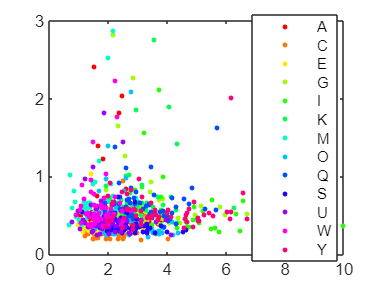

gscatter(features.AspectRatio,features.Duration,features.Character)
xlim([0 10])

## Task 2

**TASK2**

Use the `fitcknn` function to fit a model to the data. Set the `"NumNeighbors"` property to 5. Store the model in a variable called `knnmodel`. Use the model to predict the classes for the observations stored in `testdata`. Store the predictions in a variable called `predictions`.

**Hint2**

Pass the table `features` and the name `"Character"` as inputs to the `fitcknn` function. Use optional inputs to specify that the `"NumNeighbors"` property should be set to 5. Then pass `knnmodel` and `testdata` as inputs to the `predict` function.

knnmodel = fitcknn(features,"Character","NumNeighbors",5)

knnmodel =   ClassificationKNN
           PredictorNames: {'AspectRatio'  'Duration'}
             ResponseName: 'Character'
    CategoricalPredictors: []
               ClassNames: [A    C    E    G    I    K    M    O    Q    S    U    W    Y]
           ScoreTransform: 'none'
          NumObservations: 780
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


predictions = predict(knnmodel,testdata)

predictions = 260×1 categorical array
     O 
     M 
     S 
     I 
     M 
     C 
     G 
     I 
     Q 
     Q 
     I 
     E 
     C 
     W 
     Q 
     E 
     M 
     I 
     W 
     U 
     Q 
     I 
     Y 
     A 
     K 
     G 
     G 
     U 
     Q 
     Q 


## Task 3

The table `testdata` contains the known classes in the variable `Character`.

**TASK3**

Calculate the misclassification rate of the model and create a confusion chart. Store the misclassification rate in a variable called `misclass`.

**Hint3**

Perform the comparison `predictions` `~=` `testdata.Character`. Use the `sum` and `numel` functions to calculate the proportion of incorrect predictions. Pass `testdata.Character` and `predictions` as inputs to the `confusionchart` function.

misclass = sum(predictions ~= testdata.Character)/numel(predictions)

misclass = 0.7692

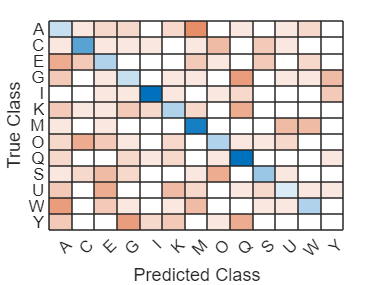

confusionchart(testdata.Character,predictions);